**Evaluación - A01734193**

Dado el sigieunte robot, calcula sus velocidades lineales y angulares:

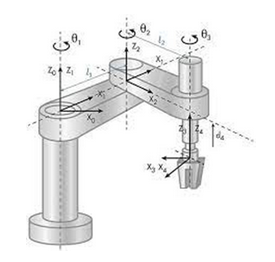        

Antes de poder calcular las velocidades correspondientes, el primer paso que se debe hacer es analizar el sistema de tal forma que se pueda  identificar el número de grados de libertad que posee y conocer cuáles son las diferentes transformaciones que se deben aplicar a cada  articulación para que lleguen a la misma referencia que la de la imagen.

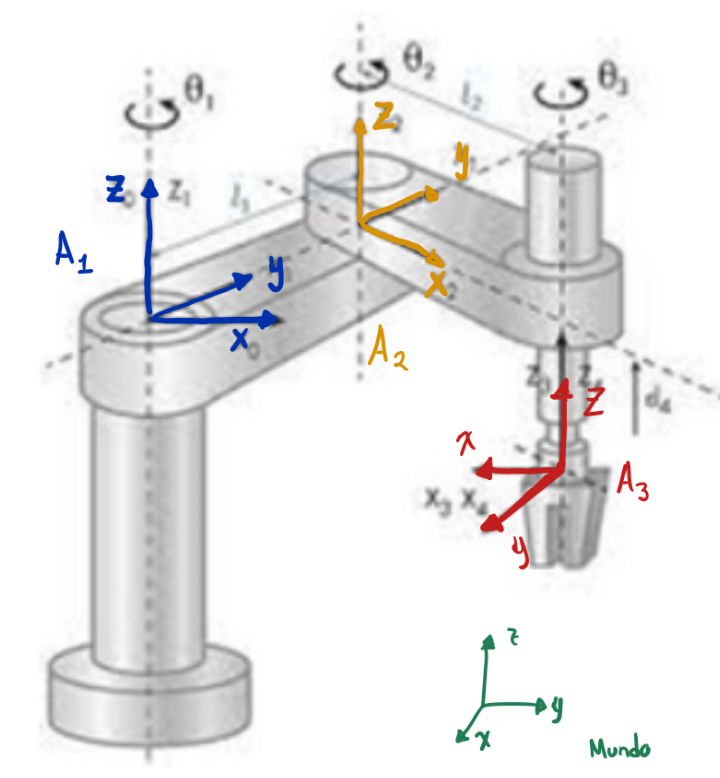

Como se puede observar en la figura anterior, el robot posee 3 grados de libertad (GLD), de las cuales todas son rotacionales, por lo que el codigo para indicar las configuraciones iniciales quedaria de al siguiente manera:

% Etapa 01 --- Declaran de parametros basicos

% Definimos el vector que repsenta el tipo de articulaciones:
% 1 --- Prismaticas
% 0 --- Rotacionales

art_t = [0 0 0];

% A la par se declaran las variables simbolicas que representaran las
% longitudes los rangos de movimeintos que pueden tener estas
% articualciones
syms th1(t) th2(t) th3(t) l1 l2 l3 ln_base t 

% Posteriroemente se crea el vector de coodernadas articulaes
pos = [th1, th2, th3];

% Calculo de los grados de libertad
GDL = size(art_t, 2);

Una vez encontradas las articualaciones y haber definido su tipo, lo que se debe de hacer es identificar cuales son los ejes de referencia individuales que cada uno de estos tiene.

Para esto primero debemos de considerar que el mundo tiene un eje de refencia inicial basado en el que nos da la regla de la mano dercha y que todas las articulaciones inician alineadas a este, por lo que es necesario transformar las referencias de cada articualacion para hacer que todas coincidan.

***Nota: ****Para esta configuración en especifico hay que tomar en cuenta la primera articulación se encuentra a una altura distinta de cero respecto al "suelo".*

**Articulación 01, 02 y 03 (Rotacional)**

Al ser una articulación rotacional, el rango de movimeinto que tiene esta misma se encuentra descrito por las funciones trigonometricas seno y coseno por lo que se establece sus configuración de la siguiente manera:

%Posición de la articulación 1 respecto al mundo
P(:,:,1) = [l1 * cos(th1); l1 * sin(th1); ln_base];

%Matriz de rotación en 'z' de la junta 1 respecto al mundo
R(:,:,1)= [cos(th1) -sin(th1)  0;
           sin(th1)  cos(th1)  0;
           0         0         1];

En la segunda linea de codigo de este bloque se indica que debe existir una rotacion en 'z',  esto porque el primer paso es alinear todos los ejes respecto al mundo.

**Articualacion 02 (Rotacional)**

En este caso como no existe cambio alguno en a orientación de los ejes, por lo que el codigo queda de la siguiente manera:

%Posición de la articulación 1 respecto a la junta 1
P(:,:,2)= [l2 * cos(th2); l2 * sin(th2); 0];

%Matriz de rotación de la junta 1 respecto a la articulacion previa
R(:,:,2)= [1 0 0;
           0 1 0;
           0 0 1];

En este caso la segunda linea del bloque de codigo anterior indica que no existe rotacion por lo que se coloca a matriz identidad

**Articualacion 3 (Rotacional)**

En este caso la siguiente articulacion se encuentra desplazada en 'z' y ademas rotada, por que el codigo queda de la siguiente manera:

%Posición de la articulación 1 respecto a la junta 2
P(:,:,3)= [l3 * cos(th3); l3 * sin(th3); -l3];

%Matriz de rotación de la junta 1 respecto a la junta 2
R(:,:,3)= [cos(th3) -sin(th3)  0;
           sin(th3)  cos(th3)  0;
           0         0         1];

En este caso la segunda linea del bloque de codigo anterior indica que debe de existir un rotacion soobre el eje 'z' para pode alinear los ejes, ademas de un cambio de poscion respecto al eje 'z' global

Una vez configuradas cada una de las partes del sistema  se procede a calcular el vector de velocidades generales

% Del mismo modo se crea el vector general de velocidades
vel = diff(pos, t)

$$vel(t) = \left(\begin{array}{ccc} \frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right) & \frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right) & \frac{\partial }{\partial t}{\mathrm{th}}_{3}\left(t\right) \end{array}\right)$$

Despues de esto se inicializan las matrices de transformacion, las cuales sirven para describir cual fue el movimiento de todo el sistema:

%Creamos un vector de ceros
Vector_Zeros = zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 

%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 

*Nota: El vector de ceros y el '1' Pue se agrega al final de cada matriz, sirven unicamente para cuadrar las matrices (4 x 4)*

*Por lo que para poder crear estas matirices de debe de hacer un ciclo que recorrra cada uno de los grados de libertad del sistema y calcule las matrices  de transformacion correspondientes para cada articulacion.*

for i = 1:GDL

    i_str= num2str(i);

   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i) = simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);

   %pretty (A(:,:,i));

   %Globales

    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);

    catch
       T(:,:,i)= A(:,:,i);

    end

    disp(strcat('Matriz de Transformación global T', i_str));

    T(:,:,i)= simplify(T(:,:,i));

    pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);

    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));

end

Matriz de Transformación global T1


[[cos(th1(t)), -sin(th1(t)),

  0, l1 cos(th1(t))],

  [sin(th1(t)), cos(th1(t)),

  0, l1 sin(th1(t))],

  [0, 0, 1, ln_base],

  [0, 0, 0, 1]]



Matriz de Transformación global T2


[[cos(th1(t)), -sin(th1(t)),

  0, l1 cos(th1(t)) + l2

   cos(th1(t) + th2(t))],

  [sin(th1(t)), cos(th1(t)),

  0, l1 sin(th1(t)) + l2

   sin(th1(t) + th2(t))],

  [0, 0, 1, ln_base],

  [0, 0, 0, 1]]



Matriz de Transformación global T3


[[#2, -#1, 0, l1 cos(th1(t)) + l2

   cos(th1(t) + th2(t)) + l3 #2],

  [#1, #2, 0, l1 sin(th1(t)) + l2

   sin(th1(t) + th2(t)) + l3 #1],

  [0, 0, 1, ln_base - l3],

  [0, 0, 0, 1]]

where

   #1 == sin(th1(t) + th3(t))

   #2 == cos(th1(t) + th3(t))




Estas matrices de transformacion resultantes van a indicar cuales son las posiciones y orientaciones finales de cada una de las articualaciones , por lo que se queremos calcular las velocidades resultantes basta con derivar estas funciones (calcular el jacobiano)

% Jacobiano de velocidades lineales y velocidades angulares
Jv_a(:,GDL) = PO(:,:,GDL);
Jw_a(:,GDL) = PO(:,:,GDL);

for k = 1:GDL

    if art_t(k)==0 

       %Para las juntas de revolución
        try

            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);

        catch

            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad

        end

    else

%         %Para las juntas prismáticas

        try

            Jv_a(:,k) = RO(:,3,k-1);

        catch

            Jv_a(:,k) = [0,0,1];

        end

            Jw_a(:,k) = [0,0,0];
            
     end

 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);

En este caso se hizo de manera analitica, pues para mi es mucho mas facil ver que es lo que pasa con cada una de las articulaciones ademas de que este metodo funciona para juntas prismaticas y rotacionales.

Finalmente se imprimen los resultados

disp('Velocidad lineal obtenida mediante el Jacobiano analitico');

Velocidad lineal obtenida mediante el Jacobiano analitico


V = simplify (Jv_a * vel');
pretty(V)

[[- #4 (l2 sin(#2) + l3 sin(#1))

   - #5 (l1 sin(th1(t)) + l2

   sin(#2) + l3 sin(#1))

   - l3 #3 sin(#1)],

  [#4 (l2 cos(#2) + l3 cos(#1))

   + #5 (l1 cos(th1(t)) + l2

   cos(#2) + l3 cos(#1))

   + l3 #3 cos(#1)],

  [0]]

where

   #1 == th1(t) + th3(t)

   #2 == th1(t) + th2(t)

         _________
          d
   #3 == -- th3(t)
         dt

         _________
          d
   #4 == -- th2(t)
         dt

         _________
          d
   #5 == -- th1(t)
         dt





disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*vel');
pretty(W)

--
|
|  [0], [0],
--

  -- _________   _________
  |   d           d
  |  -- th1(t) + -- th2(t)
  -- dt          dt

     _________ -- --
      d         |  |
   + -- th3(t)  |  |
     dt        -- --

